# Tarea: Ejemplos de SOM 

#### Juan Uriel Legaria Peña

#### Aprendizaje Computacional

En esta tarea se realizó una implementación del algoritmo de Kohonen para entrenar la red de neuronas de un mapa auto-organizado. Así mismo, se implementó el cálculo de la matriz U, la cual permie observar pliegues o huecos grandes que estén presentes en las neuronas de la red.

El algoritmo implementado se probó en 2 datasets distintos. El primero fue construido artificialmente con 1000 tonalidades aleatorias de rojo y azul, de modo que el tamaño de la matriz de datos era de $1000 \times 3$. La segunda base que se analizó fue la de iris. esta, como se ha visto en tareas anteriores se constituye de una tabla de 150 vectores, cada uno con 4 características. Las etiquetas determinan la clase de flor a la que corresponde cada vector, y puede ser de 3 tipos: Iris Setosa, Iris Versicolor e Iris Virginica.

### 1.- Ejemplo con datos de colores 

En este primer ejemplo vamos a generar datos aleatorios de tonalidades de azul y rojo como la vista en clase. Dado que en este la organización se puede apreciar visualmente, nos será de utilidad para corroborar que el algoritmo implementado se encuentra funcionando en forma adecuada. 

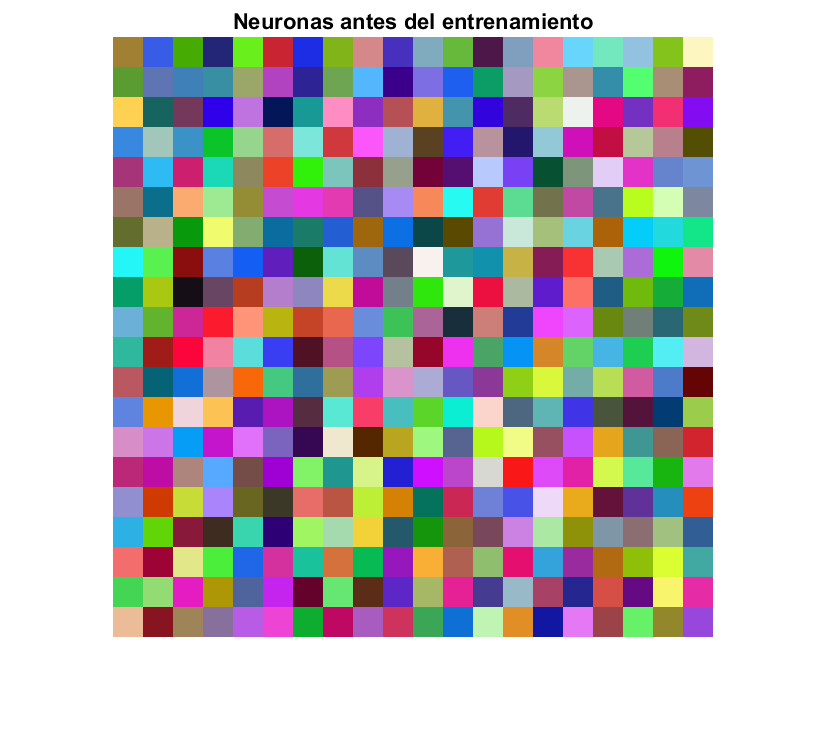

nData = 1000;
data = zeros(nData, 3);
for i = 1:floor(nData/2)
    data(i,:) = [rand(),0,0];
end

for i = floor(nData/2) +1: nData
    data(i,:) = [0,0,rand()];
end

%Definimos el mapa
widthNeurons = 20;
heightNeurons = 20;
som = SOM(data, widthNeurons, heightNeurons);

figure();
imshow(som.neurons,'InitialMagnification', 3000)
title("Neuronas antes del entrenamiento")

epochs = 10000;
learningRate = 0.9;
radius = 3;

%Entrenamos la red SOM
som = som.trainOnline(learningRate, radius, epochs);

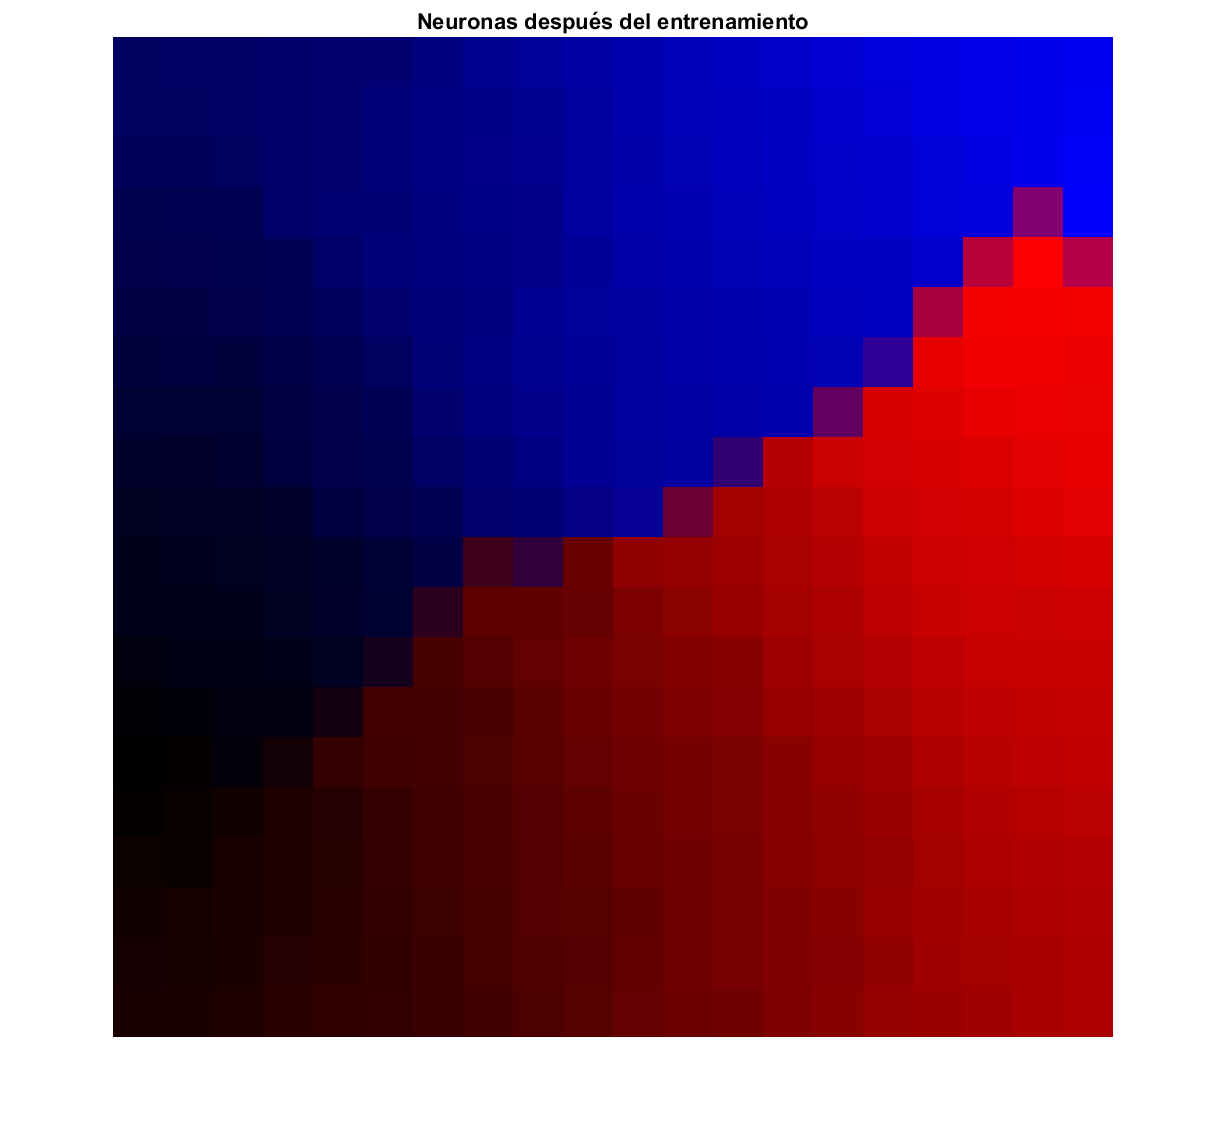

%Visualizamos
imshow(som.neurons, "InitialMagnification",5000)
title("Neuronas después del entrenamiento")

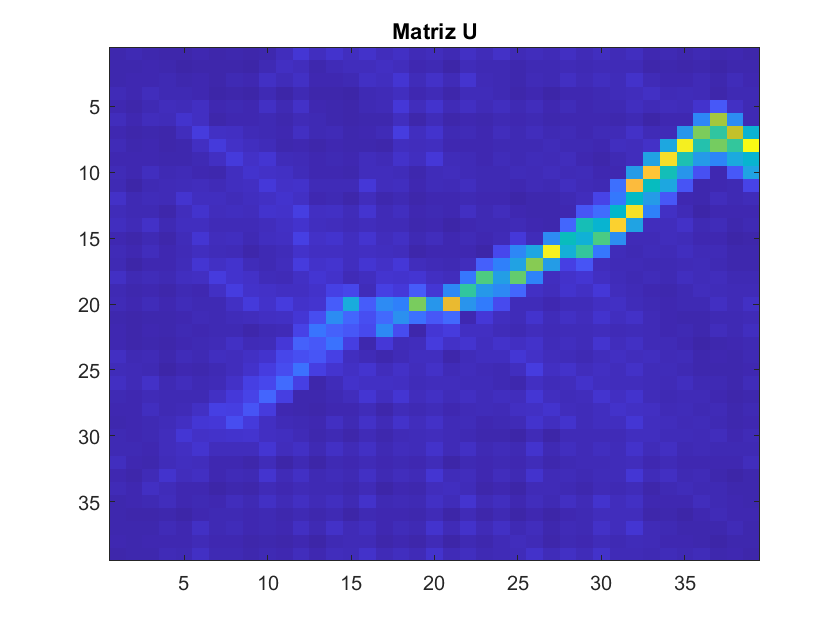

%Veamos la matriz U. 
uMatrix = som.getUMatrix();
figure()
imagesc(uMatrix)
title("Matriz U")

Algo importante a destacar sobre SOM es que el resultado final depende bastante de los pesos iniciales de las neuronas. En ocasiones, en este ejercicio de los colores, ocurria por ejemplo que se obtuviesen mas de una frontera entre rojo y azul.

### 2. Ejemplo con dataset de Iris 

Procederemos ahora a aplicar SOM al dataset de Iris.  Se comenzará como siempre con una normalización de los datos, seguido de la visualización de los mismos (aquí aplicaremos PCA para poder graficar). 

%Apertura de datos 
irisData = importdata('iris.data');
nData = length(irisData);
irisTable = zeros(nData, 4);
irisLabels = zeros(nData,1);

for i = 1:nData
    str = irisData{i};
    vector = split(str, ',');
    irisTable(i,1) = str2double(vector(1));
    irisTable(i,2) = str2double(vector(2));
    irisTable(i,3) = str2double(vector(3));
    irisTable(i,4) = str2double(vector(4));
   
    label = vector(5);
    
    if(label == "Iris-setosa")
        irisLabels(i) = 0;
    elseif(label == "Iris-versicolor")
        irisLabels(i) = 1;
    elseif(label == "Iris-virginica")
        irisLabels(i) = 2;
    end
end

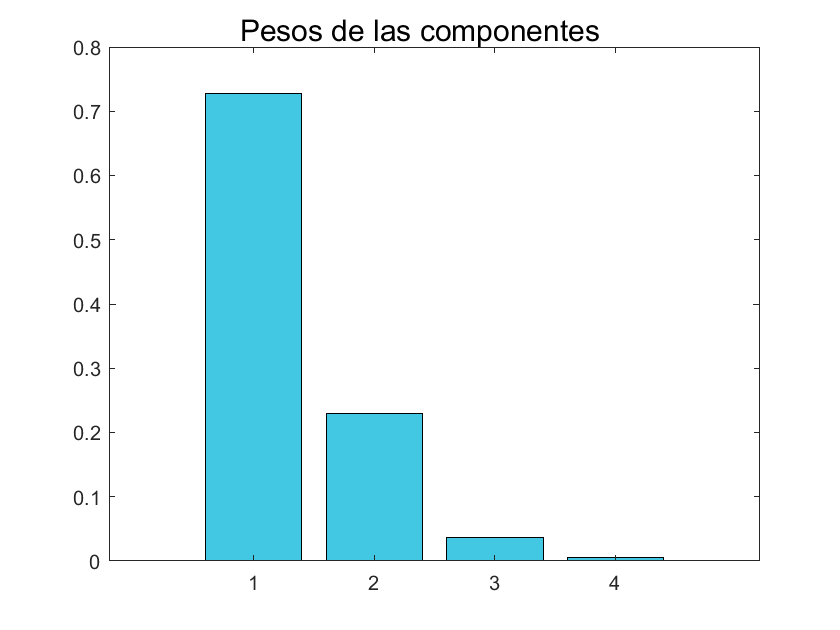

%Normalizamos los datos
dataCooker = DataPrecook();
n = size(irisTable,1);
m = size(irisTable,2);

normalizedIrisTable = zeros(n,m);
for i = 1:m
    normalizedIrisTable(:,i) = dataCooker.normalize(irisTable(:,i));
end

%Usemos PCA para poder visualizar

pcaAnalyzer = PCAAnalyzer();
covMat = pcaAnalyzer.getCovarianceMatrix(normalizedIrisTable);
[eigVals, eigVecs] = pcaAnalyzer.getComponents(covMat);

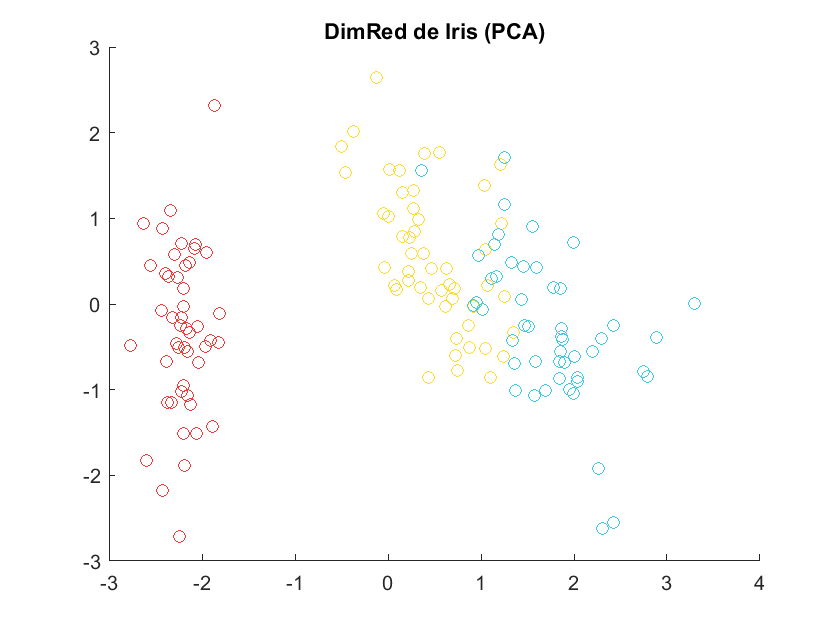

projectedIrisData = pcaAnalyzer.projectData(normalizedIrisTable,2, eigVecs);


color1 = [247/255, 54/255, 54/255];
color2 = [255/255, 220/255, 43/255];
color3 = [61/255, 202/255, 227/255];

figure()
hold on 
for i = 1:n
    vec = projectedIrisData(i,:);
    label = irisLabels(i);
    if(label == 0)
        plot(vec(1), vec(2), 'Color', color1, 'Marker','o')
    elseif(label == 1)
        plot(vec(1), vec(2), 'Color', color2, 'Marker','o')
    elseif(label == 2)
        plot(vec(1), vec(2), 'Color', color3,'Marker', 'o')
    end   
end
title("DimRed de Iris (PCA)")
hold off

%Ahora si, apliquemos SOM 
neuronsWidth = 20;
neuronsHeight = 20;
somIris = SOM(normalizedIrisTable, neuronsWidth, neuronsHeight);
%Entrenamiento
eta = 0.9;
rad = 5;
epochs = 10000;
somIris = somIris.trainOnline(eta, rad, epochs);

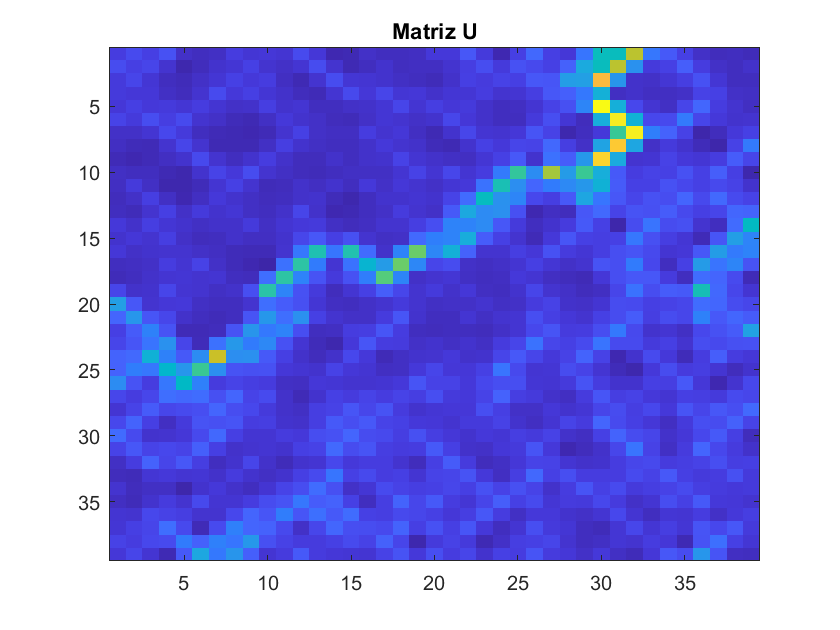

%Veamos la matriz U. 
uMatrixIris = somIris.getUMatrix();
figure()
imagesc(uMatrixIris)
title("Matriz U")

La matriz U muestra que es posible lograr una separación de dos clases distintas, sin embargo la tercera no se segmenta en forma clara. Esto es justamente uno de los retos que impone el dataset de Iris.  

Probemos ahora obtener el accuracy de la clasificación. Para ello entrenaremos una red SOM de tres neuronas. La clase asignada será el indice de la neurona mas próxima al vector que se busque clasificar.

neuronsWidth = 3;
neuronsHeight = 1;
%Dividimos end atos de entrenamiento y validación
[trainingSet, trainingSetLabels, validationSet, validationSetLabels] = dataCooker.splitData(projectedIrisData, irisLabels, 0.3);
%Entrenamos nuestro clasificador SOM
somClassification = SOM(trainingSet, neuronsWidth, neuronsHeight);
somClassification = somClassification.trainOnline(0.5, 1, 1000);
nValidation  = size(validationSet, 1);

avgAccuracy = 0;
accCalc = AccuracyCalculator();
for j = 0:2
truePositives = 0;
trueNegatives = 0;
falsePositives = 0;
falseNegatives = 0;

for i = 1:nValidation
    trueLabel = validationSetLabels(i);
    vec = validationSet(i,:);
    predictedClass = somClassification.somClassify(vec);
    if(trueLabel == j && predictedClass == trueLabel)
        truePositives  = truePositives + 1;
    elseif(trueLabel == j && predictedClass ~= trueLabel)
        falseNegatives = falseNegatives + 1;
    elseif(trueLabel ~= j && predictedClass == trueLabel)
        trueNegatives = trueNegatives + 1;
    elseif(trueLabel ~= j && predictedClass ~= trueLabel)
        falsePositives = falsePositives + 1;
    end
end

acc = accCalc.getAccuracy(truePositives, trueNegatives, falsePositives, falseNegatives);
disp("Accuracy para "+string(j)+" "+string(acc));
avgAccuracy = avgAccuracy + acc/3;
end

Accuracy para 0 0.84444
Accuracy para 1 0.84444
Accuracy para 2 0.84444



disp("La exactitud de clasificación promedio fue "+string(avgAccuracy));

La exactitud de clasificación promedio fue 0.84444


Finalmente, sería instructivo visualizar como es la frontera de clasificación que establece SOM para este problema.

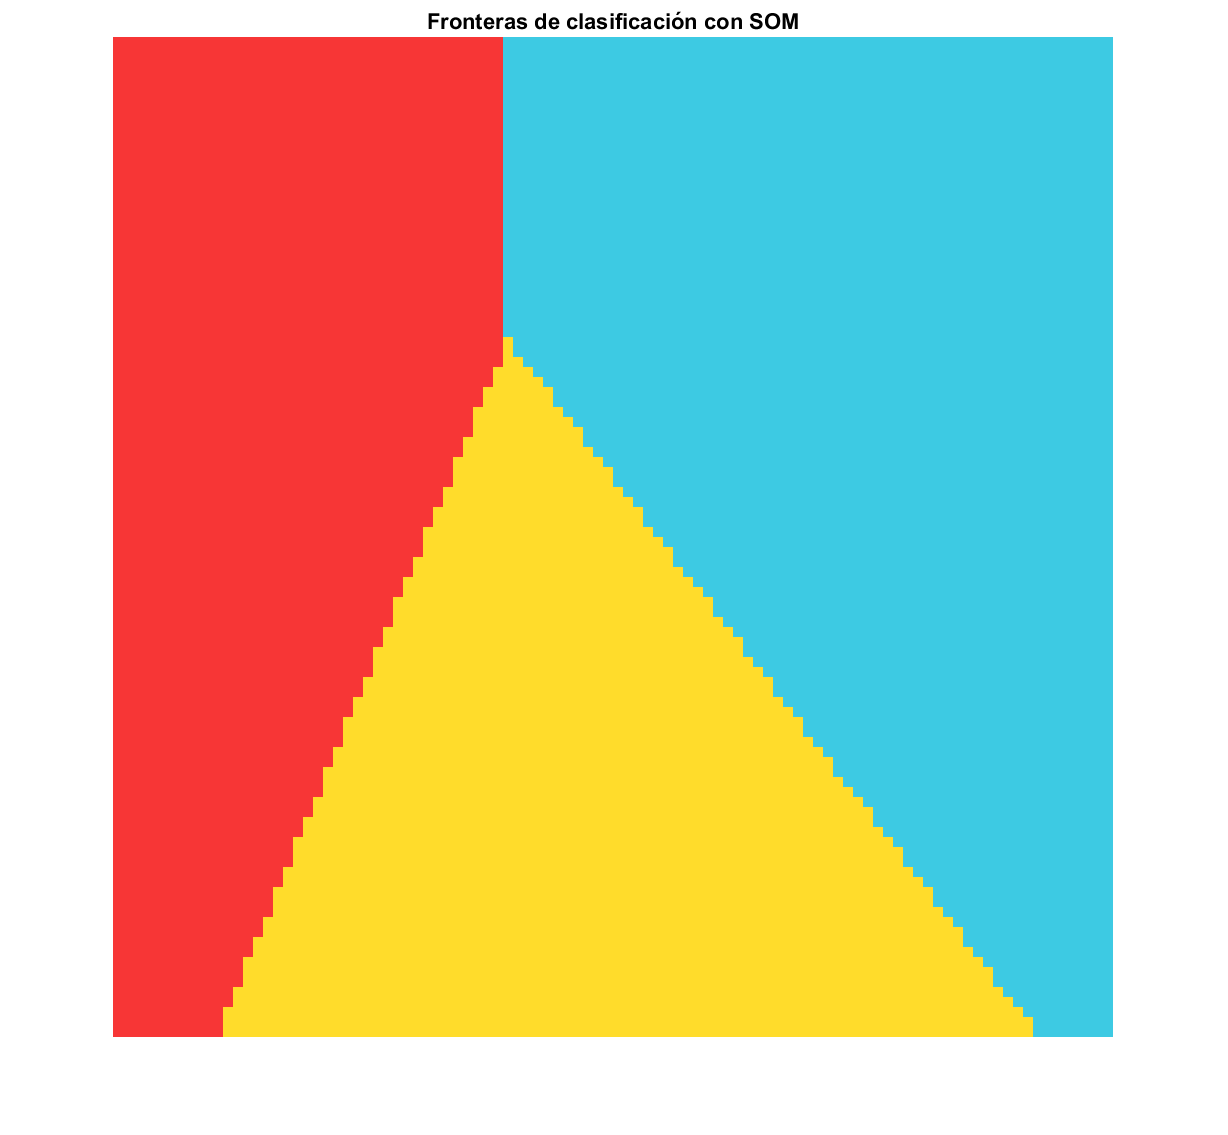


[X,Y] = meshgrid(linspace(-3,4,100), linspace(-3,3, 100));

c1 = [247/255, 54/255, 54/255];
c2 = [255/255, 220/255, 43/255];
c3 = [61/255, 202/255, 227/255];
n = size(X,1);
m = size(X,2);

colorMap = zeros(n,m,3);

for i = 1:n
    for j = 1:m
        vec = [X(i,j), Y(i,j)];
        tag = somClassification.somClassify(vec);
        if(tag == 0)
            colorMap(i,j,:) = c1;
        elseif(tag == 1)
            colorMap(i,j,:) = c2;
        elseif(tag == 2)
            colorMap(i,j,:) = c3;
        end
    end
end

figure()
imshow(colorMap,"InitialMagnification",1000 )
title("Fronteras de clasificación con SOM")